# Linear Spring-Mass-Damper System

Given specific SMD system with initial conditions and force.

Plot simulation of animation, time response and energe response (include total enrgy, kinetic energy, potential energy, damper energy cost and work from external force).

state space


$$\dot x = Ax+Bu$$



$$y = Cx + Du$$
 

where


$$x\ =\ [\ \begin{array}{c}\text{position}\\\text{velocity}\end{array}\ ]$$



$$y\ =\ [\ \text{position}\ ]$$



$$u\ =\ [\ \text{input force}\ ]$$


clear all;

If simulation is true, it will start simulating. 

If simulation is false, it will only plot the solution of time response and energy response.

simulation = false;

## Time Parameters

Ts = 0.01;                          % sample time
T = 6;                              % duration time
t = 0:Ts:T;                         % time from zero to T

## System Parameters

m = 1;                              % mass
c = 4;                              % damper
k = 6;                              % spring
u = [];                             % input

EK = [];                            % kinetic energy
U  = [];                            % potential energy
ED = [];                            % damper energy cost 
W = [];                             % work from external force
ET = [];                            % total energy

A = [0 1;-k/m -c/m];
B = [0;1/m];
C = [1 0];
D = 0;
sys = ss(A,B,C,D);                  % set transfer function

## Initial Conditions

x0 = [4;2];                         % initial state space
f = 2;                              % force
u = f*ones(T/Ts+1,1);               % set input force

## Calculation

[y,t,x]=lsim(sys,u,t,x0);           % calculate time domain response
U =  k.*x(:,1).^2/2;                % calculate Potential Energy
EK = m.*x(:,2).^2/2;                % calculate Kinetic Energy  
ED = [0;c.*x(1:end-1,2).^2*Ts];     % calculate Damper Energy Cost 
W = -[0;f.*x(1:end-1,2)*Ts];        % calculate Work form External Force
for i = 1:T/Ts
    ED(i+1) = ED(i+1)+ED(i);
    W(i+1) = W(i+1)+W(i);
end
ET = U+EK+ED+W;                     % calculate Total Energy array

## Simulation

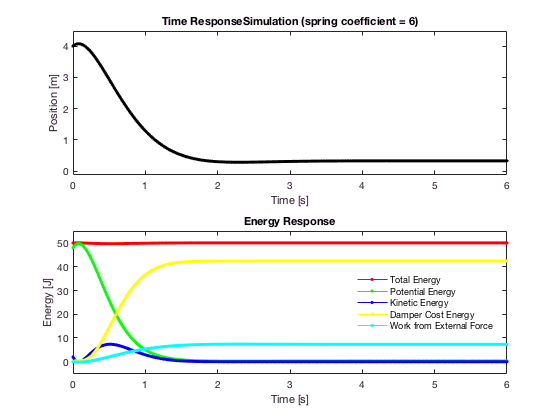

name = sprintf('Simulation (spring coefficient = %.0f)', k);
% Debug Simulation
if ~simulation
    figure(1);clf
    % plot time response
    subplot(2,1,1);
    plot(t,y,'-k.');
    axis([0 T min(0,min(y)-0.1*abs(max(y))) max(y)+0.1*abs(max(y))]);
    xlabel('Time [s]');
    ylabel('Position [m]');
    title(strcat('Time Response ',name));

    % plot energy response
    subplot(2,1,2);
    plot(t,ET,'-r.',t,U,'-g.',t,EK,'-b.',t,ED,'-y.',t,W,'-c.');
    legend('Total Energy','Potential Energy','Kinetic Energy','Damper Cost Energy','Work from External Force','Location','East');
    legend BOXOFF;
    axis([0 T min(0,min(W)-0.1*max(ET)) max(ET)*1.1]);
    xlabel('Time [s]');
    ylabel('Energy [J]');
    title('Energy Response');

% Start Simulation
else    
    % Simulation Parameters
    lengthOfEdge = 5;                               % length of the box's edge
    squareCenter = [lengthOfEdge/2 lengthOfEdge+1]; % the center of the square
    wall = round(min(x(:,1))-5);                    % the start point of the wall
    springStart = [];                               % the start point of the spring
    springEnd = [];                                 % the end point of the spring
    damperStart = [];                               % the start point of the damper
    damperEnd = [];                                 % the end point of the damper 
    
    % Start Plot 
    frame = figure(1);clf
    set(frame,'Units','centimeters','position',[5 5 40 30]);
    video = VideoWriter(strcat(name,'.avi'));
    video.Quality = 100;
    video.FrameRate = 1/Ts;
    open(video)
    for i = 1:T/Ts

        % plot time response
        subplot(2,2,3);
        plot(t(1:i),y(1:i),'-k.');
        axis([0 T min(0,min(y)-0.1*abs(max(y))) max(y)+0.1*abs(max(y))]);
        xlabel('Time [s]');
        ylabel('Position [m]');
        title('Time Response');

        % plot energy response
        subplot(2,2,4);
        plot(t(1:i),ET(1:i),'-r.',t(1:i),U(1:i),'-g.',t(1:i),EK(1:i),'-b.',t(1:i),ED(1:i),'-y.',t(1:i),W(1:i),'-c.');
        legend('Total Energy','Potential Energy','Kinetic Energy','Damper Energy Cost','Work from External Force','Location','East');
        legend BOXOFF;
        axis([0 T min(0,min(W)-0.1*max(ET)) max(ET)*1.1]);
        xlabel('Time [s]');
        ylabel('Energy [J]');
        title('Energy Response');

        %plot animation
        subplot(2,1,1);
        plotSquare(squareCenter,lengthOfEdge,y(i),0);           %plot square
        hold on
        springStart = [             wall             squareCenter(2)+lengthOfEdge/4];
        springEnd   = [squareCenter(1)-lengthOfEdge/2+y(i) squareCenter(2)+lengthOfEdge/4];
        damperStart = [             wall             squareCenter(2)-lengthOfEdge/4];
        damperEnd   = [squareCenter(1)-lengthOfEdge/2+y(i) squareCenter(2)-lengthOfEdge/4];
        plotSpring(springStart,springEnd,lengthOfEdge);         %plot spring
        plotDamper(damperStart,damperEnd,lengthOfEdge);         %plot damper
        axis([wall round(1.1*(squareCenter(1)+max(y)+lengthOfEdge))  squareCenter(2)-lengthOfEdge squareCenter(2)+lengthOfEdge]);
        xlabel('Position [m]');
        set(gca,'YTickLabel',[]);
        title(name);
        hold off

        writeVideo(video,getframe(frame));
    end
    close(video);
    % End Simulation
end